# **Capstone: Modern Control Theory**

#### System Design and Analysis: a hands-on approach

Please provide a report on the analysis of the given transformation function based on the following questions, accompanied by thorough analysis and simulation using MATLAB:

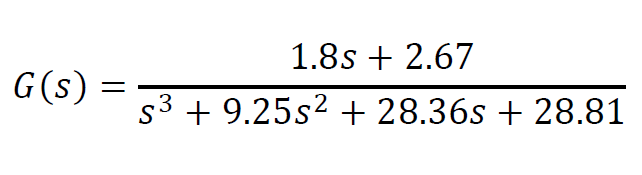

% System Transfer Function
num = [1.8, 2.67];
den = [1, 9.25, 28.36, 28.81];
sys = tf(num, den);

**1.**    Calculate the zeros and poles of the system. Determine whether the open-loop system is stable and minimum phase. Provide a detailed analysis of the system's characteristics.

% Zeros and Poles of the System
zeros = zero(tf(num, den))

zeros = -1.4833

poles = pole(tf(num, den))

poles =    -3.4599
   -3.1285
   -2.6616


To determine whether the open-loop system is stable, we can look at the locations of the poles. Since all of the poles have negative real parts, the system is *stable*.

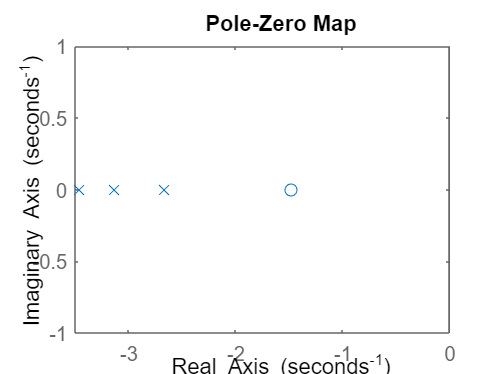

% Plotting the Zeros and Poles Location
pzplot(sys);

A minimum-phase system is a type of linear time-invariant system whose transfer function has all its poles and zeros in the left-half of the complex s-plane. As illustrated before, the system is minimum-phase since all its poles and zeros are located in the LHP.

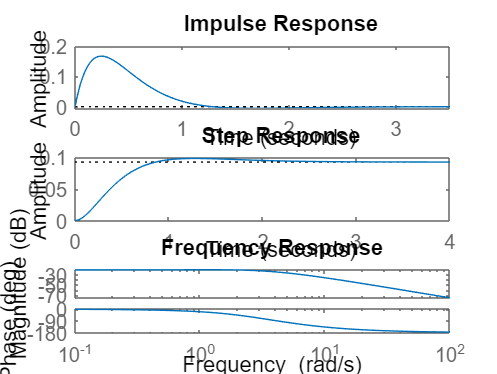

% Plotting System's Responses
figure;
subplot(3,1,1);
impulse(sys);
title('Impulse Response');
subplot(3,1,2);
step(sys);
title('Step Response');
subplot(3,1,3);
bode(sys);
title('Frequency Response');

To provide a detailed analysis of the system's characteristics, we can look at the system's impulse response, step response, and frequency response.